#### Checking Hold Percent Function

hold_percent(150,130)

ans = 0.0336

hold_percent(210,180)

ans = 0.0334

hold_percent(110,10000/110)

ans = 0.0455

#### Data Gathering

data_path = "C:\Users\wynga\OneDrive\Desktop\Synthesized Synchronization\Data\NFL 2023 to 2024 Season Money Lines.xlsx";

warning off
for week_number = 5:18
    % Action Network Data only Available after Week 4
    data_table = readtable(data_path,'Sheet',sprintf('Week %d',week_number));
    num_games = length(data_table.Teams)/2;
    for game_number = 1:num_games
        game_data(week_number,game_number).home_team = data_table.Teams{2*game_number};
        game_data(week_number,game_number).home_outcome = data_table.Outcome{2*game_number};
        game_data(week_number,game_number).home_opening_odds = data_table.OpeningMoneyline(2*game_number);
        game_data(week_number,game_number).home_best_odds = data_table.BestOdds(2*game_number);
        game_data(week_number,game_number).home_power_ranking = data_table.PowerRanking(2*game_number);
        game_data(week_number,game_number).home_bet_percent = data_table.x_OfBets(2*game_number);
        game_data(week_number,game_number).home_money_percent = data_table.x_OfMoney(2*game_number);

        game_data(week_number,game_number).away_team = data_table.Teams{2*game_number-1};
        game_data(week_number,game_number).away_outcome = data_table.Outcome{2*game_number-1};
        game_data(week_number,game_number).away_opening_odds = data_table.OpeningMoneyline(2*game_number-1);
        game_data(week_number,game_number).away_best_odds = data_table.BestOdds(2*game_number-1);
        game_data(week_number,game_number).away_power_ranking = data_table.PowerRanking(2*game_number-1);
        game_data(week_number,game_number).away_bet_percent = data_table.x_OfBets(2*game_number-1);
        game_data(week_number,game_number).away_money_percent = data_table.x_OfMoney(2*game_number-1);
    end

    for game_number = num_games+1:16
        % For Teams on a Bye Week
        game_data(week_number,game_number).home_team = 'NA';
        game_data(week_number,game_number).home_outcome = 'NA';
        game_data(week_number,game_number).home_opening_odds = nan;
        game_data(week_number,game_number).home_best_odds = nan;
        game_data(week_number,game_number).home_power_ranking = nan;
        game_data(week_number,game_number).home_bet_percent = nan;
        game_data(week_number,game_number).home_money_percent= nan;

        game_data(week_number,game_number).away_team = 'NA';
        game_data(week_number,game_number).away_outcome = 'NA';
        game_data(week_number,game_number).away_opening_odds = nan;
        game_data(week_number,game_number).away_best_odds = nan;
        game_data(week_number,game_number).away_power_ranking = nan;
        game_data(week_number,game_number).away_bet_percent = nan;
        game_data(week_number,game_number).away_money_percent = nan;
    end

end

for week_number = 1:4
    % For Weeks without Action Network Data
    for game_number = 1:16

        game_data(week_number,game_number).home_team = 'NA';
        game_data(week_number,game_number).home_outcome = 'NA';
        game_data(week_number,game_number).home_opening_odds = nan;
        game_data(week_number,game_number).home_best_odds = nan;
        game_data(week_number,game_number).home_power_ranking = nan;
        game_data(week_number,game_number).home_bet_percent = nan;
        game_data(week_number,game_number).home_money_percent= nan;

        game_data(week_number,game_number).away_team = 'NA';
        game_data(week_number,game_number).away_outcome = 'NA';
        game_data(week_number,game_number).away_opening_odds = nan;
        game_data(week_number,game_number).away_best_odds = nan;
        game_data(week_number,game_number).away_power_ranking = nan;
        game_data(week_number,game_number).away_bet_percent = nan;
        game_data(week_number,game_number).away_money_percent = nan;
    end
end

warning on

team_names = sort(horzcat({game_data(18,:).home_team},{game_data(18,:).away_team}));
% 'ARI' 'ATL' 'BAL' 'BUF' 'CAR' 'CHI' CIN' 'CLE' 'DAL' 'DEN' 'DET' 'GB'
% 'HOU' 'IND' 'JAX' 'KC' 'LAC' 'LAR' 'LV' 'MIA' 'MIN' 'NE' 'NO' 'NYG'
% 'NYJ' 'PHI' 'PIT' 'SEA' 'SF' 'TB' 'TEN' 'WAS'

#### Playing with the Data

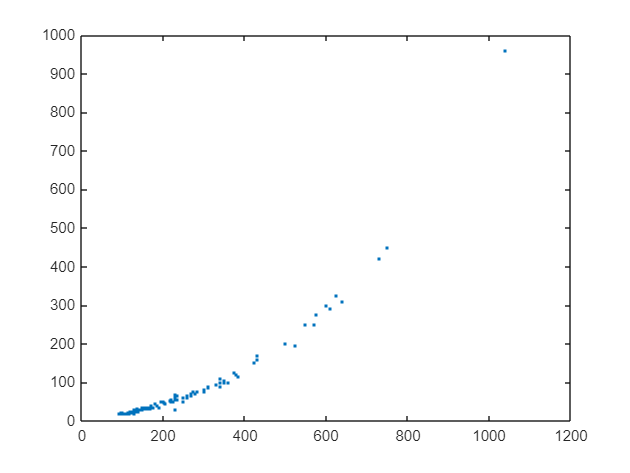

home_opening_odds = [game_data(:,:).home_opening_odds];
away_opening_odds = [game_data(:,:).away_opening_odds];

nan_value = isnan(home_opening_odds) | isnan(away_opening_odds);
home_opening_odds = home_opening_odds(~nan_value);
away_opening_odds = away_opening_odds(~nan_value);


opening_odds_pairs = [home_opening_odds; away_opening_odds];

num_pairs = length(opening_odds_pairs);
beta_values = zeros(1,num_pairs);
cent_differences = zeros(1,num_pairs);
hold_values = zeros(1,num_pairs);

for ii = 1:num_pairs
    alpha = -1*min(opening_odds_pairs(:,ii));
    beta = max(opening_odds_pairs(:,ii));

    if beta > 0
        cent_difference = alpha - beta;
        hold = hold_percent(alpha,beta);
    end

    % In Case Beta is Negative:
    if beta < 0
        cent_difference = alpha - beta - 200;
        beta = -1*1e4/beta;
        hold = hold_percent(alpha,beta);
    end

    beta_values(ii) = beta;
    cent_differences(ii) = cent_difference;
    hold_values(ii) = hold;
end

figure
plot(beta_values,cent_differences,'LineStyle','none','Marker','.')

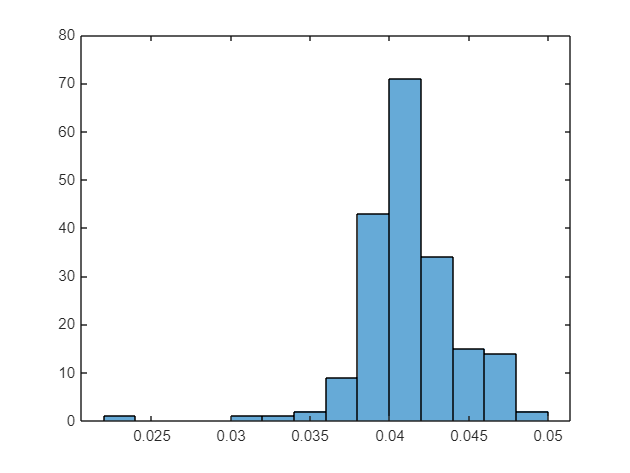

histogram(hold_values)

mean(hold_values)

ans = 0.0413

std(hold_values)

ans = 0.0031


function value = hold_percent(alpha,beta)

    % Checking the Underlying Calculations
    A = 100000;
    B = 100/alpha*(alpha+100)/(beta+100)*A;
    focal_profit = A-beta/100*B;
    complement_profit = B-100/alpha*A;
    profit_difference = abs(focal_profit-complement_profit);
    assert(profit_difference < 1)


    % The Real Calculations
    numerator = 100*(alpha-beta);
    denominator = alpha*beta+200*alpha+10000;
    value = numerator/denominator;

end